## Voltage and Current segments selection

the result shows the most suitable voltage region is [ 4.2 - 4.0 ], current segments is [ 1.0 - 0.3 ]

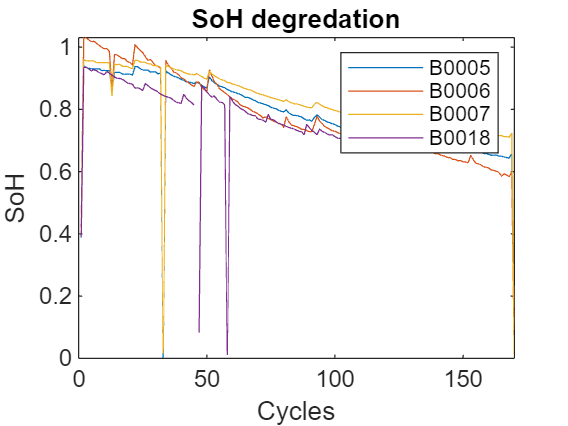

clc;clear;close all
load Data_NASA.mat
%%%
% SOH change 
SOH_05 = [Data.B0005.charge_data.SOH];
SOH_06 = [Data.B0006.charge_data.SOH];
SOH_07 = [Data.B0007.charge_data.SOH];
SOH_18 = [Data.B0018.charge_data.SOH];
figure(1)
plot(SOH_05)
hold on 
plot(SOH_06)
hold on 
plot(SOH_07)
hold on 
plot(SOH_18)
xlim([0 170])
title("SoH degredation")
xlabel('Cycles')
ylabel('SoH')
legend('B0005','B0006','B0007','B0018')
hold off

clear SOH_18 SOH_07 SOH_06 SOH_05


charge_data = Data.B0005.charge_data;
[Itrain_1, Vtrain_1] = IV(Data.B0005.charge_data);

marginI =     0.3000    1.0000


[Itrain_2, Vtrain_2] = IV(Data.B0006.charge_data);

marginI =     0.3000    1.0000


[Itrain_3, Vtrain_3] = IV(Data.B0007.charge_data);

marginI =     0.3000    1.0000


[Itrain_4, Vtrain_4] = IV(Data.B0018.charge_data);

marginI =     0.3000    1.0000


Itrain_4.data(46) = Itrain_4.data(45);
Vtrain_4.data(46) = Vtrain_4.data(45);

Itrain_4.data(47) = Itrain_4.data(48);
Vtrain_4.data(47) = Vtrain_4.data(48);

Itrain_4.data(58) = Itrain_4.data(57);
Vtrain_4.data(58) = Vtrain_4.data(57);

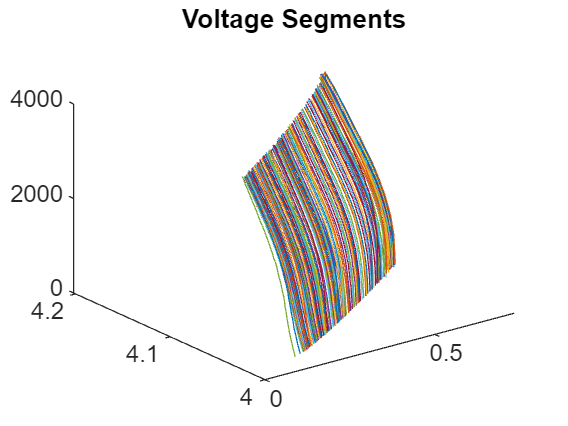

Vtrain_1.data = V_sem(Vtrain_1);
Vtrain_2.data = V_sem(Vtrain_2);
Vtrain_3.data = V_sem(Vtrain_3);
Vtrain_4.data = V_sem(Vtrain_4);
figure(1)
for i=1:length(Itrain_1.data)
    plot3(Vtrain_1.data{i}(3,:),Vtrain_1.data{i}(2,:),Vtrain_1.data{i}(1,:))
    hold on
end
title('Voltage Segments')

save NASAtrain_V Vtrain_1 Vtrain_2 Vtrain_3 Vtrain_4

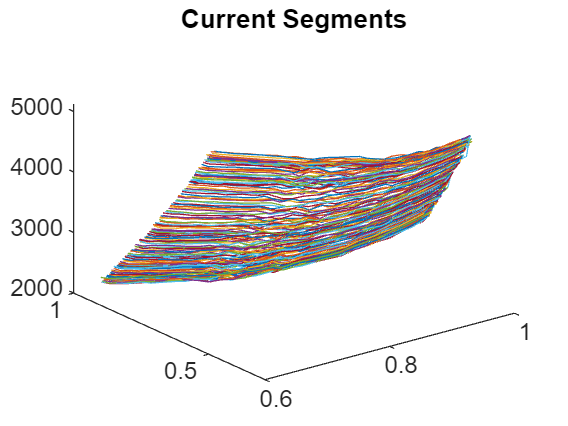

Itrain_1.data = I_sem(Itrain_1);
Itrain_2.data = I_sem(Itrain_2);
Itrain_3.data = I_sem(Itrain_3);
Itrain_4.data = I_sem(Itrain_4);
figure(2)
for i=1:length(Itrain_1.data)
    plot3(Itrain_1.data{i}(3,:),Itrain_1.data{i}(2,:),Itrain_1.data{i}(1,:))
    hold on
end
title('Current Segments')

save NASAtrain_I Itrain_1 Itrain_2 Itrain_3 Itrain_4

%Select V sem
function data = V_sem(DataIn)
data= cell([length(DataIn.data),1]);
for i = 1:length(DataIn.data)
    DataIn.data{i};
    Voltage = DataIn.data{i}(2,:);
    deltaV = 0.005;
    sum_V = 0;
    VoltageSeq(1) = DataIn.data{i}(2,1);
    TimeSeq(1) = DataIn.data{i}(1,1);
    SoCSeq(1) = DataIn.data{i}(3,1);
    
    Sequence_num = 2;
    for k=2:length(Voltage)
       sum_V=sum_V+(Voltage(k)-Voltage(k-1));
       if sum_V>=deltaV
           sum_V=0;
           VoltageSeq(Sequence_num)=DataIn.data{i}(2,k);
           TimeSeq(Sequence_num)=DataIn.data{i}(1,k);
           SoCSeq(Sequence_num)=DataIn.data{i}(3,k);
           Sequence_num=Sequence_num+1;
       end
    end
    data{i} = [TimeSeq; VoltageSeq; SoCSeq];
end
end
%Select I sem
function data = I_sem(DataIn)
data= cell([length(DataIn.data),1]);
for i = 1:length(DataIn.data)
    DataIn.data{i};
    Current = DataIn.data{i}(2,:);
    deltaI = 0.02;
    sum_I = 0;
    CurrentSeq(1) = DataIn.data{i}(2,1);
    TimeSeq(1) = DataIn.data{i}(1,1);
    SoCSeq(1) = DataIn.data{i}(3,1);
    
    Sequence_num = 2;
    for k=2:length(Current)
       sum_I=sum_I-(Current(k)-Current(k-1));
       if sum_I>=deltaI
           sum_I=0;
           CurrentSeq(Sequence_num)=DataIn.data{i}(2,k);
           TimeSeq(Sequence_num)=DataIn.data{i}(1,k);
           SoCSeq(Sequence_num)=DataIn.data{i}(3,k);
           Sequence_num=Sequence_num+1;
       end
    end
    data{i} = [TimeSeq; CurrentSeq; SoCSeq];
end
end



function [I, V] = IV(charge_data)
% Data collection

cycle_num = width(charge_data);

% voltage sagment
start_voltage = 4.0; 
end_voltage = 4.2; 
marginV = [start_voltage end_voltage];
Vsem= {};

for i = 2:cycle_num-1
    index = find(charge_data(i).voltage > start_voltage);
    start_index = index(1);
    index = find(charge_data(i).voltage > end_voltage);
    end_index = index(1);  
    Vsem{i} = [charge_data(i).Time(start_index:end_index);charge_data(i).voltage(start_index:end_index);charge_data(i).SOC(start_index:end_index)];
end
Vsem(33) = Vsem(32);
Vsem(1) = Vsem(2);

V.data = Vsem';


% current sagment
start_current = 1.0; 
end_current = 0.3; 
marginI = [end_current start_current]
Isem= {};

for i = 2:cycle_num-1
    index = find(charge_data(i).current < start_current & charge_data(i).current>0.1);
    start_index = index(1);
    index = find(charge_data(i).current < end_current & charge_data(i).current>0.1);
    end_index = index(1);  
    Isem{i} = [charge_data(i).Time(start_index:end_index);charge_data(i).current(start_index:end_index);charge_data(i).SOC(start_index:end_index)];
end
Isem(33) = Isem(32);
Isem(1) = Isem(2);
I.data = Isem';

SoH = zeros([cycle_num-1, 1]);
for i = 2:cycle_num-1
    SoH(i) = charge_data(i).SOH;
end

I.label = SoH;
V.label = SoH;
I.label(33) = SoH(32);
I.label(1) = SoH(2);
I.label(46) = SoH(45);
I.label(47) = SoH(48);
I.label(58) = SoH(57);

V.label(33) = SoH(32);
V.label(1) = SoH(2);
V.label(46) = SoH(45);
V.label(47) = SoH(48);
V.label(58) = SoH(57);




end